% 1. Media y Desviación Estándar
clc
datos = readtable('ESTADISTICA.xlsx');

altura = datos(:,1);
altura = table2array(altura);
talla = datos(:,2);
talla = table2array(talla);

Ma = mean(altura);
disp("La media de la estatura es: "+Ma+" cm")

La media de la estatura es: 167.095 cm


sigmaa = std(altura);
disp("La desviación estándar de la estatura es: "+sigmaa+" cm")

La desviación estándar de la estatura es: 9.3795 cm


Mt = mean(talla);
disp("La media de la talla de calzado es: "+Mt+" cm")

La media de la talla de calzado es: 25.7975 cm


sigmat = std(talla);
disp("La desviación estándar de la talla del calzado es: "+sigmat+" cm")

La desviación estándar de la talla del calzado es: 1.8689 cm


%2. Ecuaciones Gaussianas

disp("Las funciones Gaussianas de Distribucion Normal para Estatura y Talla son:")

Las funciones Gaussianas de Distribucion Normal para Estatura y Talla son:


mu1 = "mu_estatura = 166.6400";
displayFormula(mu1)

$$\mu_{\mathrm{estatura}}=166.64$$

sigma1 = "sigma_estatura = 10.7983";
displayFormula(sigma1)

$$\sigma_{\mathrm{estatura}}=10.7983$$

s = "f(x) = 1/(sigma_estatura*sqrt(2*pi)) * exp(-((x-mu_estatura)^2)/(2*sigma_estatura^2))";
displayFormula(s)

$$f\left(x\right)=\frac{1}{\sigma_{\mathrm{estatura}}\,\sqrt{2\,\pi }}\,{\mathrm{e}}^{\frac{-{\left(x-\mu_{\mathrm{estatura}}\right)}^{2}}{2\,{\sigma_{\mathrm{estatura}}}^{2}}}$$


mu2 = "mu_talla = 25.7550";
displayFormula(mu2)

$$\mu_{\mathrm{talla}}=25.755$$

sigma2 = "sigma_talla = 1.9028";
displayFormula(sigma2)

$$\sigma_{\mathrm{talla}}=1.9028$$

s = "f(x) = 1/(sigma_talla*sqrt(2*pi)) * exp(-((x-mu_talla)^2)/(2*sigma_talla^2))";
displayFormula(s)

$$f\left(x\right)=\frac{1}{\sigma_{\mathrm{talla}}\,\sqrt{2\,\pi }}\,{\mathrm{e}}^{\frac{-{\left(x-\mu_{\mathrm{talla}}\right)}^{2}}{2\,{\sigma_{\mathrm{talla}}}^{2}}}$$

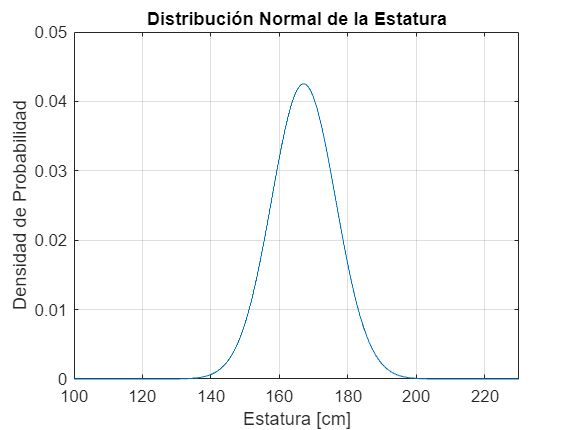

% 3. Gráfica de Histogramas y Funciones Gaussianas

% Estatura
x = linspace(0,250,1000);
y = (1/(sigmaa*sqrt(2*pi())))*exp(-((x-Ma).^2)/(2*sigmaa^2)); % Distribución Normal de Estatura
plot(x,y)
xlim([100 230])
ylim([0 0.05])
title("Distribución Normal de la Estatura")
xlabel("Estatura [cm]")
ylabel("Densidad de Probabilidad")
grid on

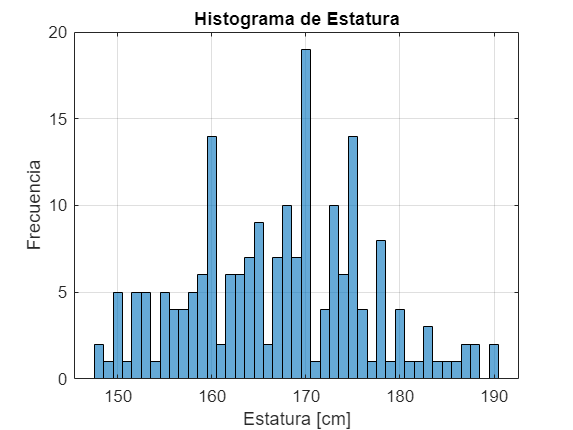


ax2 = gca;
chart2 = ax2.Children(1);


histogram(altura) % Histograma de estatura
title("Histograma de Estatura")
xlabel("Estatura [cm]")
ylabel("Frecuencia")
grid on

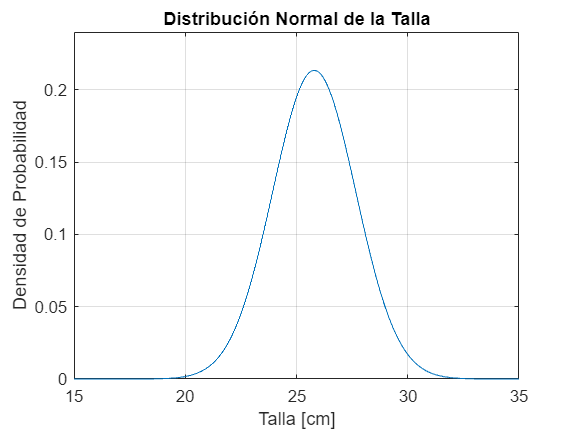


%Talla

x = linspace(10,40,1000);
y = (1/(sigmat*sqrt(2*pi())))*exp(-((x-Mt).^2)/(2*sigmat^2)); % Distribución Normal de la Talla
plot(x,y)
xlim([15 35])
ylim([-0.005 0.23])
title("Distribución Normal de la Talla")
xlabel("Talla [cm]")
ylabel("Densidad de Probabilidad")
grid on

xlim([15 35])
ylim([0 0.24])

ax = gca;
chart = ax.Children(1);


h = histogram(talla) % Histograma de altura

h =   Histogram with properties:

             Data: [200×1 double]
           Values: [4 28 34 29 34 39 21 11]
          NumBins: 8
         BinEdges: [22 23 24 25 26 27 28 29 30]
         BinWidth: 1
        BinLimits: [22 30]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


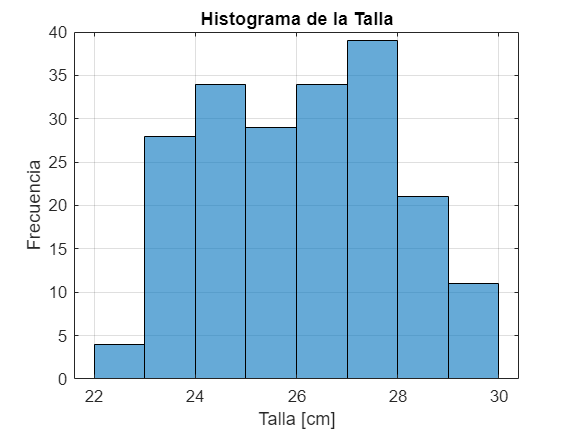

title("Histograma de la Talla")
xlabel("Talla [cm]")
ylabel("Frecuencia")
grid on

% 4. Probabilidad 
syms x
y = (1/(sigmaa*sqrt(2*pi())))*exp(-((x-Ma).^2)/(2*sigmaa^2));
pa = double(int(y,Ma-sigmaa,Ma+sigmaa)); 
disp("La probabilidad de que una persona aleatoria caiga en el rango de una desviación estándar "+newline+"para la estatura es: "+pa*100+"%")

La probabilidad de que una persona aleatoria caiga en el rango de una desviación estándar 
para la estatura es: 68.2689%


y = (1/(sigmat*sqrt(2*pi())))*exp(-((x-Mt).^2)/(2*sigmat^2));
pt = double(int(y,Mt-sigmat,Mt+sigmat));
disp("La probabilidad de que una persona aleatoria caiga en el rango de una desviación estándar"+newline+" para la talla es: "+pt*100+"%")

La probabilidad de que una persona aleatoria caiga en el rango de una desviación estándar
 para la talla es: 68.2689%


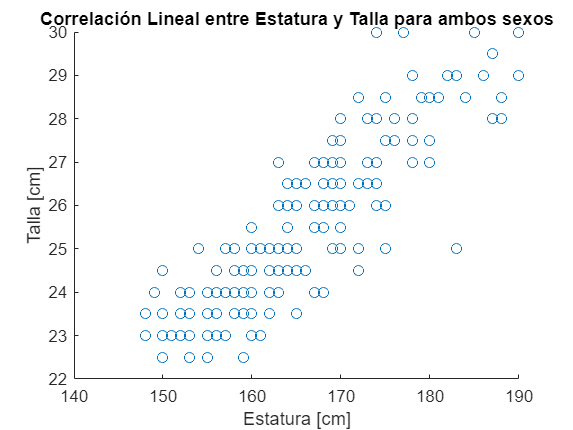

% 5. Relación Lineal entre Estatura y Calzado

datosm=readtable('ESTADISTICA.xlsx','Sheet','masculino');
datosf=readtable('ESTADISTICA.xlsx','Sheet','femenino');

alturam = datosm(:,"Estatura");
alturam = table2array(alturam);
tallam = datosm(:,"Talla");
tallam = table2array(tallam);

alturaf = datosf(:,"Estatura");
alturaf = table2array(alturaf);
tallaf = datosf(:,"Talla");
tallaf = table2array(tallaf);

scatter(altura,talla)
title("Correlación Lineal entre Estatura y Talla para ambos sexos")
xlabel("Estatura [cm]")
ylabel("Talla [cm]")

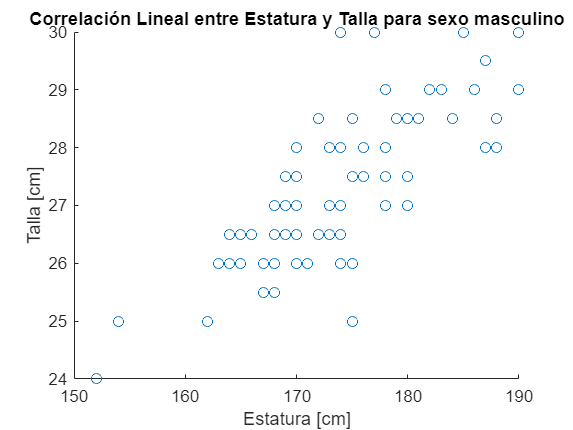

scatter(alturam,tallam)
title("Correlación Lineal entre Estatura y Talla para sexo masculino")
xlabel("Estatura [cm]")
ylabel("Talla [cm]")

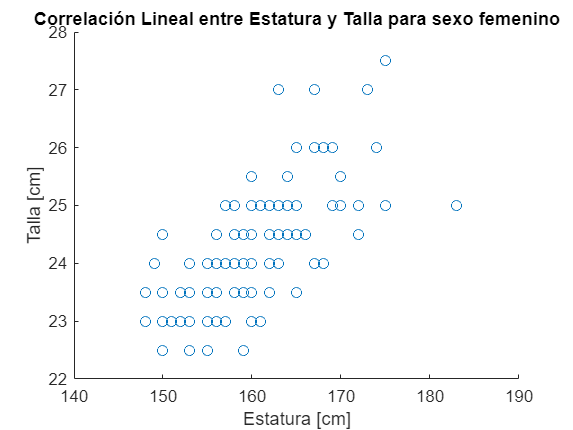

scatter(alturaf,tallaf)
title("Correlación Lineal entre Estatura y Talla para sexo femenino")
xlabel("Estatura [cm]")
ylabel("Talla [cm]")